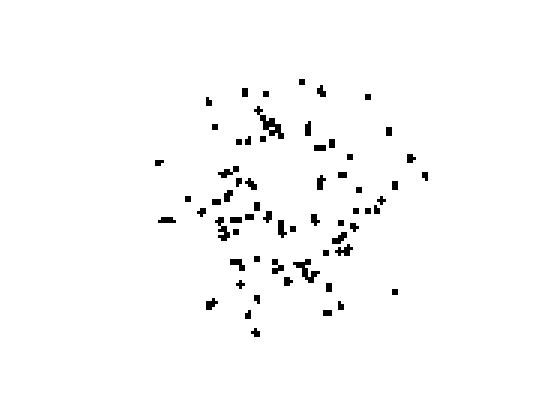


dir = 0;  speed = 1;
%s   = mkDots([39 39 50], dir,  speed,  0.15);
a = load(fullfile(tBevRootPath, 'analysisOutput', 'exampleStim.mat'));
s = a.mdIm(:, :, 1 : 40);

pars = shPars;
flipBook(s); % fots moving from left to right

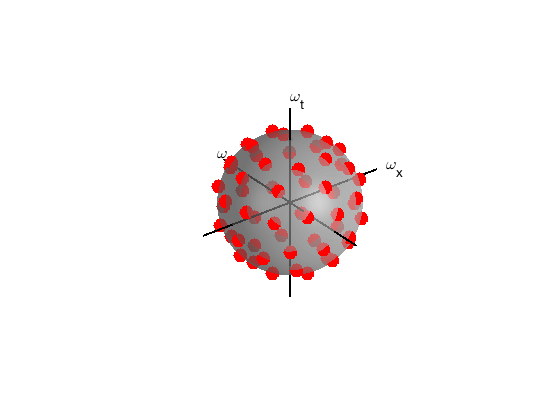

nStages = 6;

% v1 linear (tuned to different directions)
[pop{1}, ind{1}] = shModel(s, pars, 'v1lin');
% v1 simple
[pop{2}, ind{2}] = shModel(s, pars, 'v1simple');
% v1 complex (changing matrix size)
[pop{3}, ind{3}] = shModel(s, pars, 'v1complex');
% mt lin (tuned to different population velocities)
[pop{4}, ind{4}] = shModel(s, pars, 'mtlin');
% mt halfrect (changing matrix size)
[pop{5}, ind{5}] = shModel(s, pars, 'mthalfrect');
% mt pattern
[pop{6}, ind{6}] = shModel(s, pars, 'mtpattern');

% v1 neuron preference: orientation and ratio of temporal versus spatial frequency
% (e.g. [1.9, 1.5] means prefers to the motion to the left and slightly up, at a speed of 1.5 cycles per frame)

% mt neuron preference: preferred motion direction and speed (e.g. [0, 1], moving to the right at the speed of 1 pixel/frame)
for k = 1 : nStages
    rsp{k} = reshape(pop{k}, [ind{k}(2, 2), ind{k}(2, 3), ind{k}(2, 4), size(pop{k}, 2)]);
end
% 1 population defined by the preferred direction of motion, and the raito of temporal to spatial frequency

% The version of the model implemented here uses a population of V1
% neurons whose peak spatio-temporal frequency values lie on the
% surface of a sphere in the Fourier domain.
% In this version, all neurons are at the same scale.

% shShowV1PopulationDirectionsDots(pars.v1PopulationDirections);
% example v1 linear responses:
v1lin = squeeze(rsp{6}(180, 180, :, :));

figure (1), clf

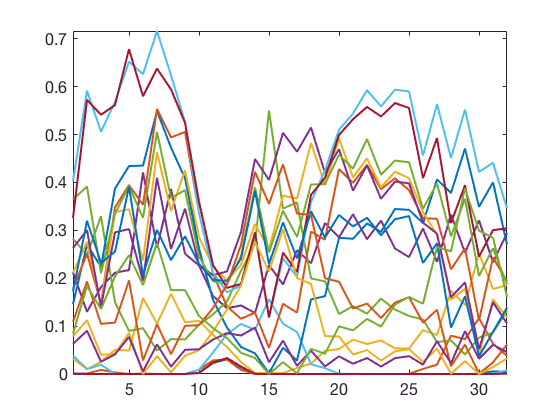

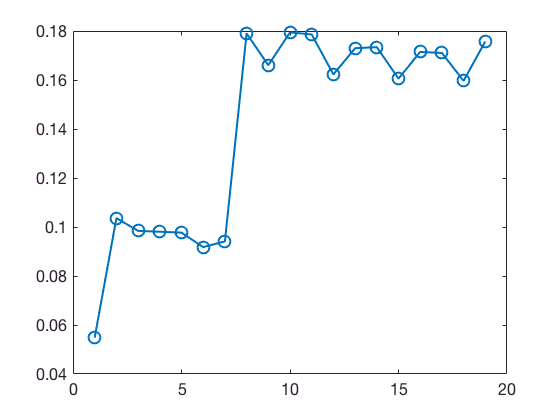

ans =          0         0
         0    1.0000
    1.0472    1.0000
    2.0944    1.0000
    3.1416    1.0000
    4.1888    1.0000
    5.2360    1.0000
    0.2618    6.0000
    0.7854    6.0000
    1.3090    6.0000


plot(v1lin), axis tight
mtrsp = squeeze(mean(mean(mean(rsp{6}, 1), 2), 3));
mttcrsp = squeeze(mean(mean(rsp{6}, 1), 2));
figure (2), clf
plot(mtrsp, 'o-')
pars.mtPopulationVelocities